## Direct Stiffness Methods:

## Question 1:

    if false
    % Question 1 % Axial (1D -  Fixed Springs)
    clc; clear;
    syms k1 k2 k3 u1 u2 u3 u4 P %defines as algebraic variables and not values
    % Derive The Element Stiffness Matrix For Loads and Stiffnesses
    % k and U matrix
    base_matrix = [1 -1; -1, 1]; %1D stiffness matrix
    k_values = [k1 k2 k3]; %designated stiffness values
    U_matrix = [u1, u2, u3, u4]'; %nodal matrix

### Part A:

    numNodes = 4; %number of nodes
    K_global = sym(zeros(numNodes)); %creates 4x4 matrix of 0's
    elemNodes = [1 3; 3 4; 4 2]; %node connections by element
    
    for i = 1:size(elemNodes,1) % 1:3
        nodes = elemNodes(i,:); % stores the nodes one by one for each i interval so i = 1 => [1,3]
        k_matrix = base_matrix * k_values(i); % calculate element stiffness matrix
        
        K_global(nodes(1),nodes(1)) = K_global(nodes(1),nodes(1)) + k_matrix(1,1);
        K_global(nodes(1),nodes(2)) = K_global(nodes(1),nodes(2)) + k_matrix(1,2);
        K_global(nodes(2),nodes(1)) = K_global(nodes(2),nodes(1)) + k_matrix(2,1);
        K_global(nodes(2),nodes(2)) = K_global(nodes(2),nodes(2)) + k_matrix(2,2);
    end
    

### Part B:

    % assign assembled global stiffness to variable used below
    k_matrix = K_global;

### Part C:

    % boundary conditions
    u1 = 0;
    u2 = 0;

### Part D:

    % displacements of nodes with the load P that acts at node 4 (splice matrix where u1 and u2 equate to 0)
    K_reduced = K_global([3 4], [3 4]); % takes rows 3 & 4 and columns 3 & 4
    F_reduced = [0, P]'; %takes F vector

    % Solve for the reduced displacements using the reduced stiffness matrix
    U_reduced = K_reduced \ F_reduced;
    u3 = U_reduced(1);
    u4 = U_reduced(2);
    end

## Question 2:

if false
% Question 2 % (Two-Spring Assemblage)
clc; clear;
syms u2
% Matrices and Known Values
k1 = 1000; %N/m
k2 = 3000; %N/m
u1 = 0; %fixed condition
u3 = 20*10^-3;
F2 = 0;
base_matrix = [1 -1; -1 1];
k_values = [k1 k2];
U_matrix = [u1, u2, u3];

% Simplifying Equations
numNodes = 3; % amount of nodes
K_global = zeros(numNodes); % 3x3 matrix full of 0's
elemNodes = [1 2; 2 3] % element by element for nodal values

for i = 1:size(elemNodes, 1)
    nodes = elemNodes(i,:); % stores the nodes one by one for each i interval so i = 1 => [1,3]
    k_matrix = base_matrix * k_values(i); % calculate element stiffness matrix

    K_global(nodes(1),nodes(1)) = K_global(nodes(1),nodes(1)) + k_matrix(1,1);
    K_global(nodes(1),nodes(2)) = K_global(nodes(1),nodes(2)) + k_matrix(1,2);
    K_global(nodes(2),nodes(1)) = K_global(nodes(2),nodes(1)) + k_matrix(2,1);
    K_global(nodes(2),nodes(2)) = K_global(nodes(2),nodes(2)) + k_matrix(2,2);
end

k_matrix = K_global;

% Reduce Global Stiffness Matrix Given That We Know The Displacements At u1 And u3
K_reduced = K_global(2, 2); % splice out the u1 and u3 known values.
F_reduced = [F2 - K_global(2,1)*u1 - K_global(2,3)*u3]; % 1x1 Matrix for F2 due to unknown u2

% Finding Forces, Nodal Displacements, and Reaction Forces
U_reduced = K_reduced \ F_reduced; % solves for u2
u2 = U_reduced;
U_final = [u1, u2, u3]'; % complete displacement vector in meters
F3 = K_global(3,:) * U_final; % takes 3rd row and multiplies via known displacements to get F3
F_final = K_global * U_final; % nodal force vector
F_spring1 = k1 * (u2 - u1); % force in spring 1
F_spring2 = k2 * (u3 - u2); % force in spring 2
end


## Question 3:

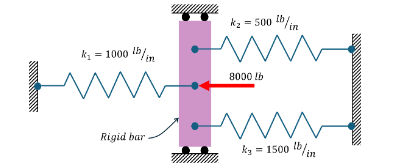

if false
% Question 3 %
clc; clear;
syms u2 F1 F3 F4
% Base Matrices and Known Values
k1 = 1000; %lb/in
k2 = 500; %lb/in 
k3 = 1500; %lb/in
F2 = 8000; 
u1 = 0; u3 = 0; u4 = 0;
base_matrix = [1 -1; -1 1];
k_values = [k1 k2 k3];
u_matrix = [u1 u2 u3 u4]';

% Define the global stiffness matrix for the new question
numNodes = 4;
K_global = sym(zeros(numNodes)); % Initialize a new global stiffness matrix
elemNodes = [1 2; 2 3; 2 4]; % Define element connections for the new setup

for i = 1:size(elemNodes, 1)
    nodes = elemNodes(i,:); % stores the nodes one by one for each i interval
    k_matrix = base_matrix * k_values(i); % calculate element stiffness matrix

    K_global(nodes(1),nodes(1)) = K_global(nodes(1),nodes(1)) + k_matrix(1,1);
    K_global(nodes(1),nodes(2)) = K_global(nodes(1),nodes(2)) + k_matrix(1,2);
    K_global(nodes(2),nodes(1)) = K_global(nodes(2),nodes(1)) + k_matrix(2,1);
    K_global(nodes(2),nodes(2)) = K_global(nodes(2),nodes(2)) + k_matrix(2,2);
end

k_matrix = K_global; % returns the global as our k_matrix

% Simplified Matrices
K_reduced = K_global(2,2); % reduces the global stiffness matrix to the unknown u2 value
F_reduced = [F2 - K_global(2,1)*u1 - K_global(2,3)*u3 - K_global(2,4)*u4] % F2 formula should just equate to 8000 since every displacement node is at 0.

$$F\_reduced = 8000$$

U_reduced = K_reduced \ F_reduced; % finds u2
u2 = U_reduced; % brings U_reduced to u2

% Final Matrices
U_final = [u1, u2, u3, u4]'; % shows the nodal displacements
F_final = K_global * U_final; % shows force vector
% Element 1: k1 between nodes 1 and 2
Fe1 = k1*(u2 - u1);
f1_element = [-Fe1; Fe1];

% Element 2: k2 between nodes 2 and 3
Fe2 = k2*(u3 - u2);
f2_element = [-Fe2; Fe2];

% Element 3: k3 between nodes 2 and 4
Fe3 = k3*(u4 - u2);
f3_element = [-Fe3; Fe3];
end
